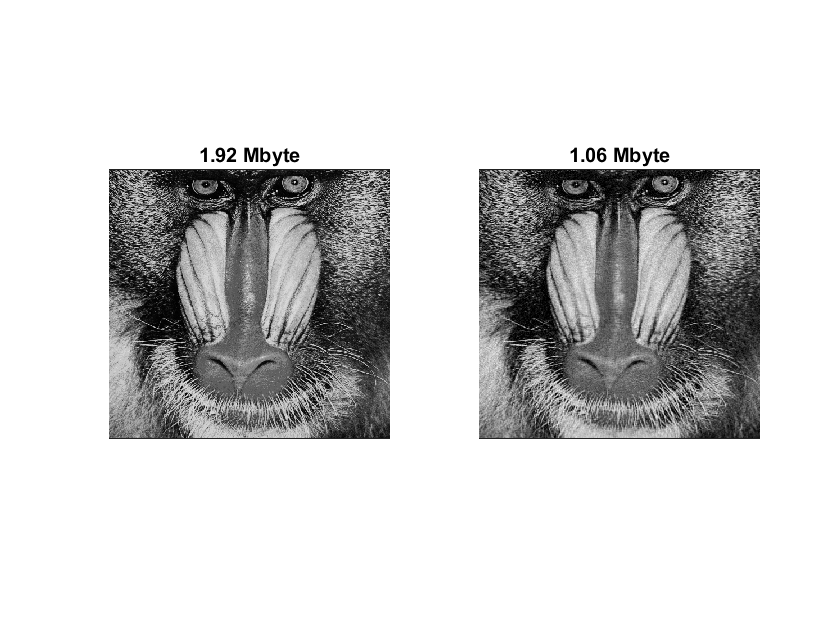

% Simple idea of how to compress an image

% I studied liner algebra using this book: 
% https://www.wiley.com/en-ck/Contemporary+Linear+Algebra-p-9780471163626
% The cover page in this book (monkey images) indicates this image
% compresssion concept. 

load mandrill X

% SVD image compression
imgGD = X./255;

% SVD on the original matrix
[U,S,V] = svd(imgGD);



% N: # of singular values
N = 120;

% Truncate U,S,V
Un = U(:,1:N);
Sn = S(1:N,1:N);
Vn = V(:,1:N);

% Calculate compressed matrix
imgGDComp = Un*Sn*Vn';


byte2MegaByte = 10^6;
figure;
fileSizeimgGD = getfield(whos('imgGD'), 'bytes');
subplot(121); imshow(imgGD); title(sprintf('%0.2f Mbyte', fileSizeimgGD./byte2MegaByte));
fileSizeimgGDComp = getfield(whos('Un'), 'bytes') + getfield(whos('Sn'), 'bytes') + getfield(whos('Vn'), 'bytes');
subplot(122); imshow(imgGDComp); title(sprintf('%0.2f Mbyte', fileSizeimgGDComp./byte2MegaByte));

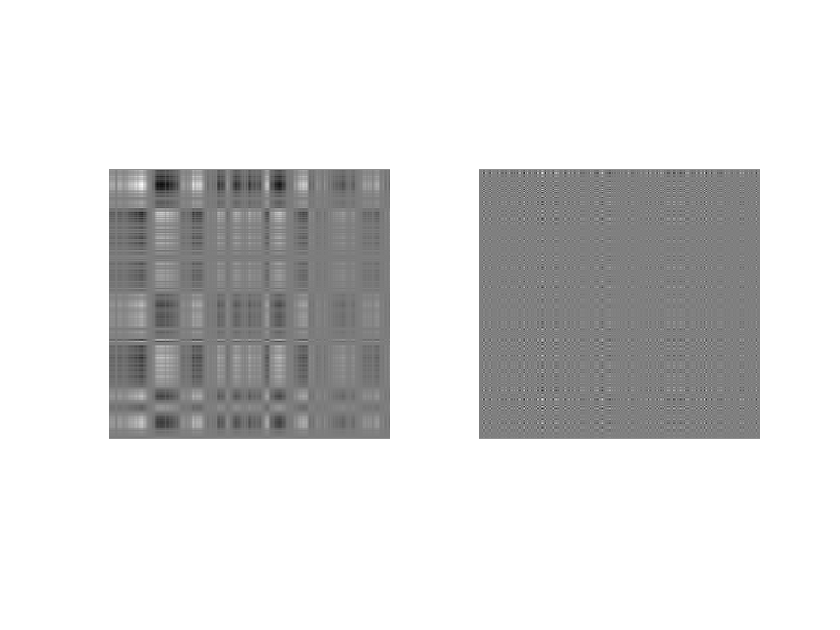



figure;
subplot(121); imshow(rescale(U(:,5).*V(:,5)'));
subplot(122); imshow(rescale(U(:,100).*V(:,100)'));

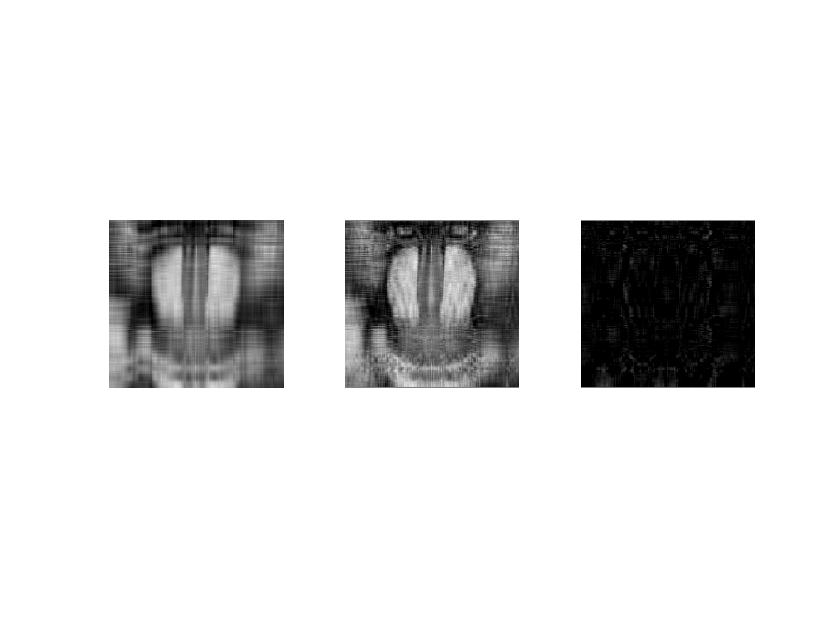



% image 1
N = 5;

% Truncate U,S,V
Un = U(:,1:N);
Sn = S(1:N,1:N);
Vn = V(:,1:N);

% Calculate compressed matrix
img1 = Un*Sn*Vn';

% image 2
N = 10;

% Truncate U,S,V
Un = U(:,1:N);
Sn = S(1:N,1:N);
Vn = V(:,1:N);

% Calculate compressed matrix
img2 = Un*Sn*Vn';

img3 = img2-img1;

figure;
subplot(131); imshow(img1);
subplot(132); imshow(img2);
subplot(133); imshow(img3);